# **Final Project**

Group Members: Madeline Laesser, Jade Lecker, Hudson McGaughey

### Introduction

    The main theme of our project is looking at fluvial dunes. Fluvial dunes are dunes that occur when a fluid interacts with an erodible bed beneath it. In our case, we will be looking at dunes on the bed of rivers with sand on the floor. Specifically, we will look at a canonical evolution equation that can solve for the height of the dune over the movement across the horizontal axis of the river bed. We are using an equation from a paper called the Mathematical Modeling of Dune Formation by David Cocks. 

    The study of fluvial dunes can be important for the health of the river’s ecosystem and predicting/preventing floods. According to a paper in the Journal of Geophysical Research called *The Fluid Dynamics of River Dunes: A Review and Some Future Research Directions*, fluvial dunes are “vital in predicting flow resistance, sediment transport, and deposition within many rivers.” Some examples of how knowing this is important are as follows. A higher flow resistance corresponds to slower flow right which can cause higher water levels and subsequently, flooding. Sediment deposition can modify the river bed which can affect the river’s ability to carry flood waters. Different river species need different river flow conditions. Predicting these flow conditions can help us manage habitats. Overall, the study of fluvial dunes can give us insight into the protection of the environment.

    Since this class is at the undergraduate level, the model and equation we are using are more simplified than might be used in other studies. The paper by David Cocks that we found our equation in actually takes the equation a few steps further. Our equation is a fairly simple PDE, but the paper takes the Fourier transform and uses the Fourier spectral method. In our project, we attempt to solve it multiple ways, but all of them are different from the Fourier spectral method. Also, there are different models and equations based on assumptions. We made the assumption that we have a saturated bedload transport, but in other people’s work they use models that have a non-saturated bedload transport. Another method for studying fluvial dunes is by using data collected from tools like flume experiments and vibrocorers. An example of this is found in an article by Kleinhans over fluvial dunes in a river in the Netherlands. Methods that rely on collecting data can be difficult because of the challenges that come with measuring sediment in river beds. Lastly, the boundary conditions we chose to use may be different in other people's work as we had trouble finding information on the boundary conditions, so we chose some that made the most sense to us. 

### Equations

**Canonical Evolution Equation**

**2.196       **                     $\frac{\partial S}{\partial T}+S\frac{\partial S}{\partial X}=\frac{\partial^2 S}{\partial X^2 }-\int_0^{\infty } \frac{\partial^2 S}{\partial X^2 }\left(X-\xi ,t\right)\xi^{-\frac{1}{3}} d\xi$

**Rewritten Canonical Evolution Equation**

**2.197  **                                ${\mathit{\mathbf{s}}}_{\mathit{\mathbf{t}}} +{\textrm{ss}}_{\mathit{\mathbf{x}}} +\mathit{\mathbf{K}}*{\mathit{\mathbf{s}}}_{\textrm{xx}} -{\mathit{\mathbf{s}}}_{\textrm{xx}} =0$

**Burger's Equation**


$$\frac{\partial u}{\partial t}+u\frac{\partial u}{\partial x}+u\frac{\partial u}{\partial y}=v\frac{\partial^2 u}{\partial u^2 }+v$$

$$\frac{\partial^2 u}{\partial y^2 }$$


Modeling dunes in a riverbed is easier than the desert, as the water is confined to a channel, making the flow of water simpler than the wind. The physical processes in the creation and deposition of fluvial dunes depends on the the flow rate of the water above it, as well as the composition of the riverbed and the sediment. The force of the river moves the particles, causing them to either be deposited downstream or move along the surface of the bed. "Dunes more slowly in the direction of low, and have a shallow upstream slope with a steep downstream slope" (Cocks 2005). Dunes form as the water flow in a river begins to increase, beginning with small ripples in the surface of the bed. 

The form of the canonical evolution equation in 2.197 is derived by a Fourier spectral method; however, its initial form in 2.196 is related to Burger's equation, which is a fundemental partial differential equation that evaluates convection-diffusion. In this context, a canonical evolution, or canonical transformation, refers to an equation that describes how a vector changes over time, a useful tool when evaluating adaptive dynamics.

**Parameters**

In the initial canonical evolution equation, 2.196, S refers to the mean slope of the bed, X is horizontal length defined in meters, T is a non-specified unit of time, and $\xi$ is an integration term.

In the rewritten canonical evolution equation of 2.197, the terms as described are s, the bed slope elevation, $s_t$, the time derivative of the bed slope elevation, $s_x$, the time derivative of the bed slope elevation, $s_{\textrm{xx}}$, the second time derivative of the bed slope elevation, and finally, K, which is the convolution kernel. A convolution expresses the amount of overlap between functions, or in other words, "blending" of two functions. In 2.197, it is the inverse of the cube root of horizontal length.

**Initial Conditions**


$$\begin{array}{l}
\hat{s=\;s} e^{\sigma t+i\left(\mathrm{kx}+\mathrm{ly}\right)} \\
K\left(x\right)=x^{-\frac{1}{3}} \\
x_0 =0\\
t_0 =0\\
C=\frac{\mathrm{dx}}{\mathrm{dt}}=100\\
D=\frac{\mathrm{dx}}{{\mathrm{dt}}^2 }=10,000
\end{array}$$


**Boundary conditions**

For our project, we used different boundary conditions to test this dune model. To begin, we used a no flux boundary condition, meaning that convection and diffusion terms are in balance.


$${***s}_x =0,s_t =0$$


Then, we implemented a periodic boundary, meaning that any particle that leaves the system will re-enter the system. It essentially becomes a loop where output is equivalent to the input. This boundary condition helps evaluate infinite systems by creating a box model that can be replicated repeatedly for an infinite period of time. 

**Assumptions**

Assumptions made in this model begin with simplfying the dune model. By changing the values of some of the variables to a constant, the equation becomes easier to evaluate. In this case, by assuming the initial bed elevation to be greater than 1 over a length of greater than 1,  many of the variables are eliminated, resulting in 2.196, the canonical evolution equation. To further simply this equation, 2.196 is given a solution by a Fourier spectral method, as the integral is a convolution. 

For our evaluation of the model, we will be looking at 2.197 over a horizontal length of 1000 meters with a step of 1 meter and a time length of 100 years with a time step of 0.01 years.

### Numerical Methods

**Advection-Diffusion Equation**

**Canonical Evolution Equation**

**2.196       **                     $\frac{\partial S}{\partial T}+S\frac{\partial S}{\partial X}=\frac{\partial^2 S}{\partial X^2 }-\int_0^{\infty } \frac{\partial^2 S}{\partial X^2 }\left(X-\xi ,t\right)\xi^{-\frac{1}{3}} d\xi$

**Rewritten Canonical Evolution Equation**

**2.197  **                                ${\mathit{\mathbf{s}}}_{\mathit{\mathbf{t}}} +{\textrm{ss}}_{\mathit{\mathbf{x}}} +\mathit{\mathbf{K}}*{\mathit{\mathbf{s}}}_{\textrm{xx}} -{\mathit{\mathbf{s}}}_{\textrm{xx}} =0$

To numerically solve the rewritten canonical evolution equation 2.197 from the text, we used the numerical method of the advection-diffusion equation, as the left side of 2.196, initial canonical evolution equation, the equation contains convecting waves on the left-hand side that form shocks and a diffusive term on the right-hand side, "stabilizing short-wavelength distrubances and smoothing out shocks" (Cocks). The dunes model describes the formation of dunes through turbulent geophysical flow, which describes the physical interpretation of how the particles are moved within a system due to advection and diffusion.

**CODE**

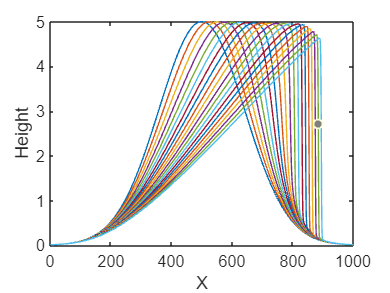

% horizontal length
x0 = 0;
xf = 1000;

% time
t0 = 0;
tf = 100;

% time steps
dx = 1;
dt = .01;

% initial conditions
C = dt/dx;
D = dt/dx.^2;
nx = (xf-x0)/dx;
nt = (tf-t0)/dt;
x = linspace(x0,xf,nx);
t = linspace(t0,tf,nt);
K = x.^(-1/3);
s = zeros(nx,nt);
s(:,1) = 5*exp(-(.005*x-2.5).^2);

for k = 1:nt-1
    for i = 2:nx-1
        s(i,k+1) = -C*(s(i,k)).^2 + s(i,k) * (1 + C*s(i-1,k)+2*D*(K(i)-1)) - D*(K(i)-1)*(s(i-1,k)+s(i+1,k));
    end
    s(1,k+1) = s(2,k+1);
    s(end,k+1) = s(end-1,k+1);
end

% plotting
plot(x,s(:,1:500:end));
xlabel('X');
ylabel('Height');

### Results

*What simulations did you run with this model?*

*Describe the results*

*How do the results compare with any known solutions, or data?*

*How do the results change with different methods, time steps, grid spacing, or model parameters?*

*What did the model tell you about the process you were studying?*

*How could the model be improved in terms of methods used or processes included?*

### Figures

*At least 4 figures describing results*

*Have all axes labeled *

*Variables have units*

*Everything is readable*

*Colors, lines, countours, etc. are all easy to discern*

**REFERENCES**

Cocks, D. (2005). Mathematical modelling of dune formation.

### Video Walkthrough

*TBD*